clc
clear all
close all

sequence=getgenbank('OU398982');%random sample accession number from NCBI; National Center for Biotechnology Information
seqviewer(sequence)

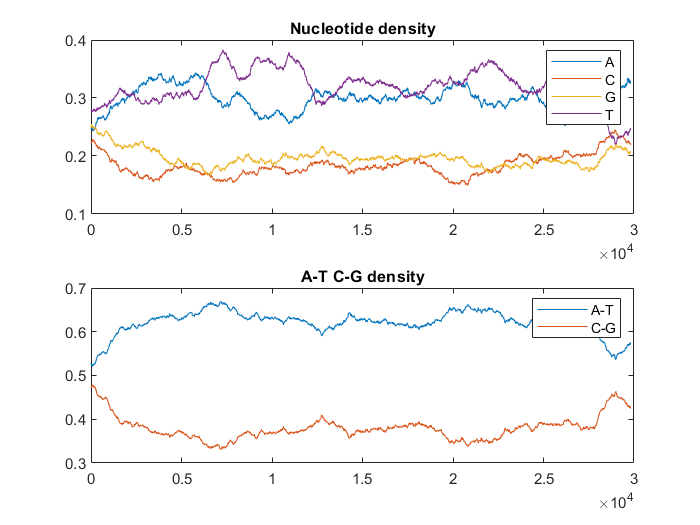


figure
ntdensity(sequence)%nucleotide density; how much AT-GC

bases = basecount(sequence)%how many bases

bases = struct with fields:
    A: 8905
    C: 5467
    G: 5850
    T: 9590


compBases = basecount(seqrcomplement(sequence))%AT-GC complements

compBases = struct with fields:
    A: 9590
    C: 5850
    G: 5467
    T: 8905


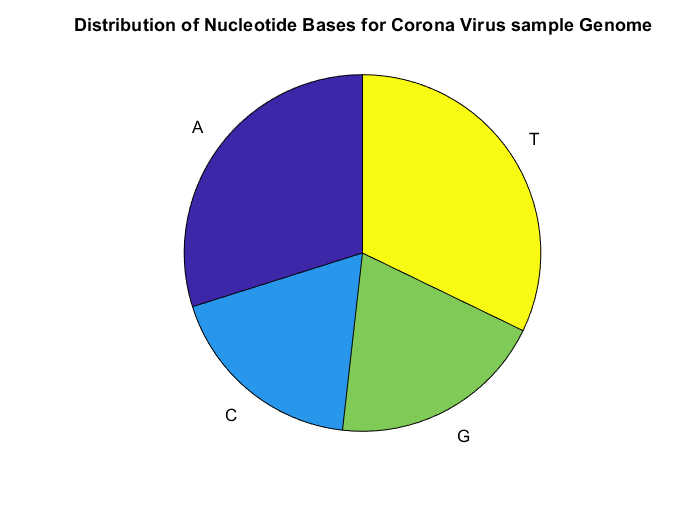

figure
basecount(sequence,'chart','pie');
title('Distribution of Nucleotide Bases for Corona Virus sample Genome');

figure
dimers = dimercount(sequence,'chart','bar')

dimers = struct with fields:
    AA: 2844
    AC: 2014
    AG: 1736
    AT: 2311
    CA: 2079
    CC: 878
    CG: 435
    CT: 2075
    GA: 1608
    GC: 1167
    GG: 1087
    GT: 1987
    TA: 2373
    TC: 1408
    TG: 2592
    TT: 3217


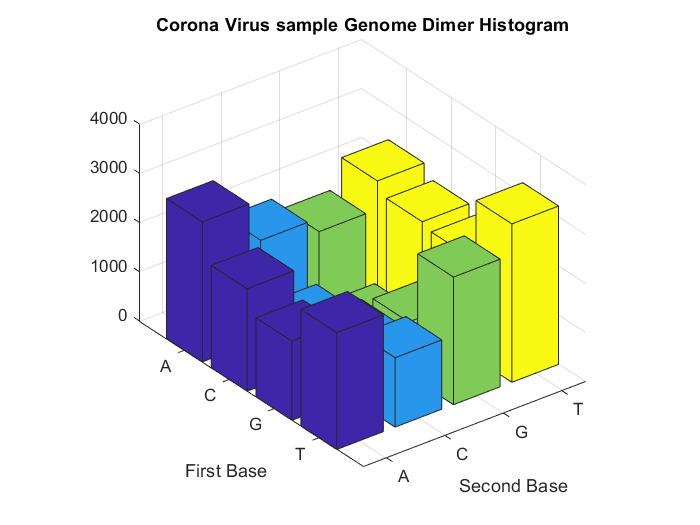

title('Corona Virus sample Genome Dimer Histogram');

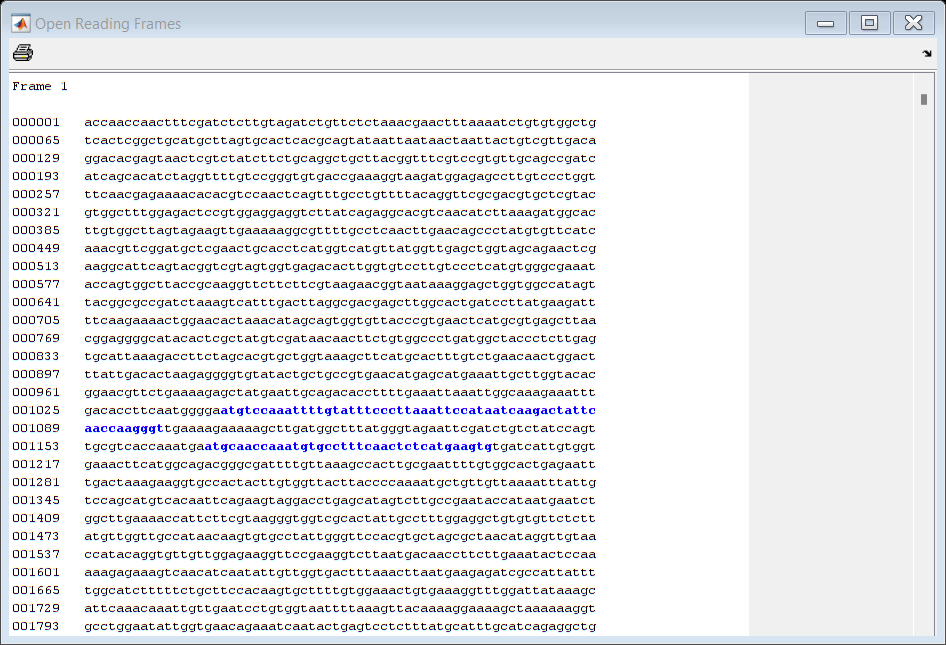

sewageorfs=seqshoworfs(sequence);

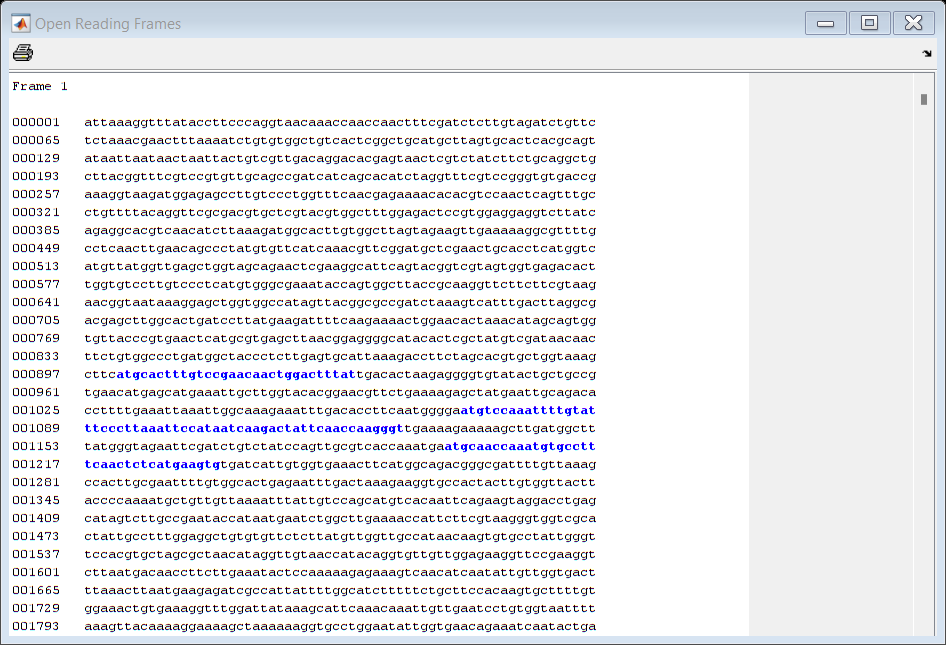



Refer=getgenbank('NC_045512');%original sequence accession number
origin=Refer.Sequence;
seqviewer(origin)
realorfs=seqshoworfs(origin);

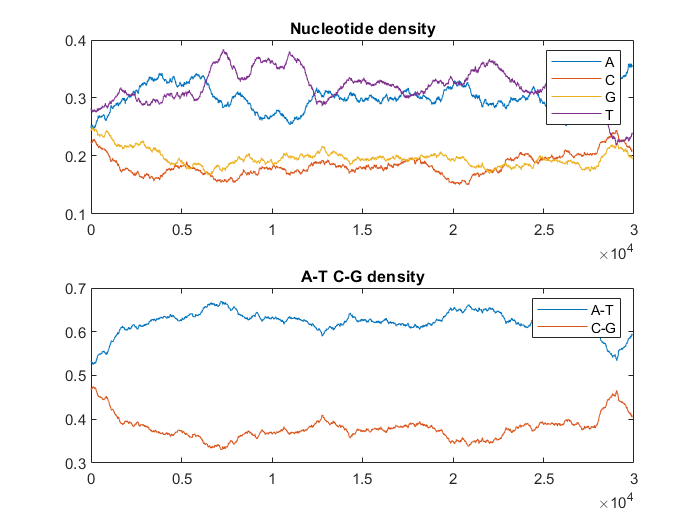

figure
ntdensity(origin)

bases = basecount(origin)

bases = struct with fields:
    A: 8954
    C: 5492
    G: 5863
    T: 9594


compBases = basecount(seqrcomplement(origin))

compBases = struct with fields:
    A: 9594
    C: 5863
    G: 5492
    T: 8954


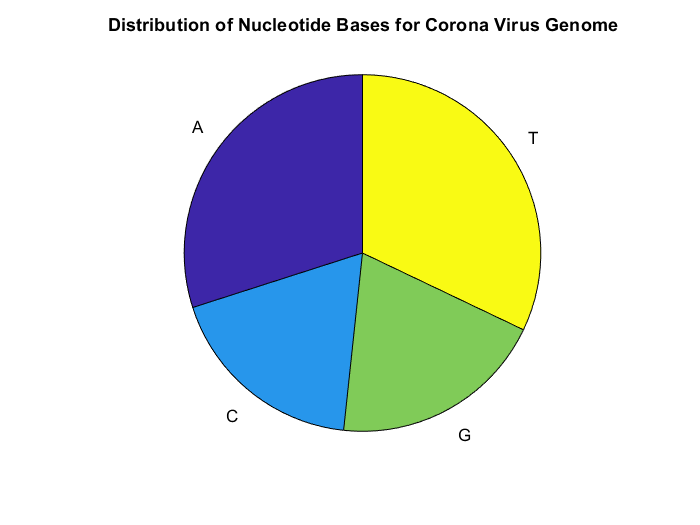

figure
basecount(origin,'chart','pie');
title('Distribution of Nucleotide Bases for Corona Virus Genome');

figure
dimers = dimercount(origin,'chart','bar')

dimers = struct with fields:
    AA: 2880
    AC: 2023
    AG: 1742
    AT: 2308
    CA: 2084
    CC: 888
    CG: 439
    CT: 2081
    GA: 1612
    GC: 1168
    GG: 1093
    GT: 1990
    TA: 2377
    TC: 1413
    TG: 2589
    TT: 3215


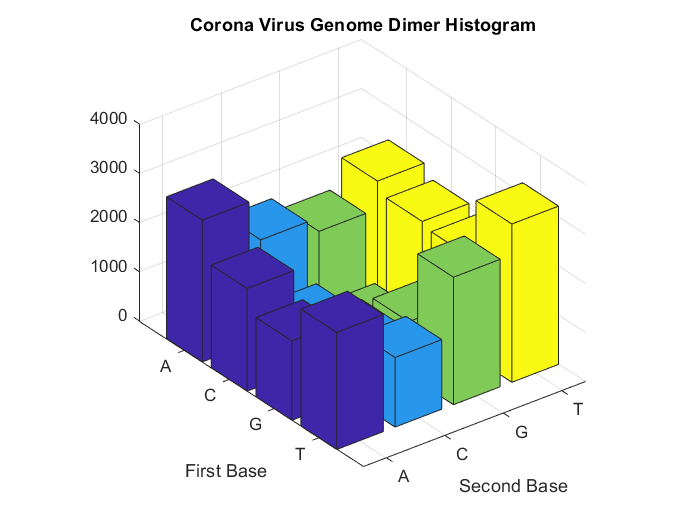

title('Corona Virus Genome Dimer Histogram');




sewageprotein = nt2aa(sequence),%nucloetide to amino acid

sewageprotein = 'TNQLSISCRSVL*TNFKICVAVTRLHA*CTHAV*LITNYCR*QDTSNSSIFCRLLTVSSVLQPIISTSRFCPGVTER*DGEPCPWFQRENTRPTQFACFTGSRRARTWLWRLRGGGLIRGTSTS*RWHLWLSRS*KRRFAST*TALCVHQTFGCSNCTSWSCYG*AGSRTRRHSVRS*W*DTWCPCPSCGRNTSGLPQGSSS*ER**RSWWP*LRRRSKVI*LRRRAWH*SL*RFSRKLEH*T*QWCYP*THA*A*RRGIHSLCR*QLLWP*WLPS*VH*RPSSTCW*SFMHFV*TTGLY*H*EGCILLP*T*A*NCLVHGTF*KEL*IADTF*N*IGKEI*HLQWGMSKFCISLKFHNQDYSTKG*KEKA*WLYG*NSICLSSCVTK*MQPNVPFNSHEV*SLW*NFMADGRFC*SHLRILWH*EFD*RRCHYLWLLTPKCCC*NLLSSMSQFRSRT*A*SCRIP**IWLENHSS*GWSHYCLWRLCVLLCWLP*QVCLLGSTC*R*HRL*PYRCCWRRFRRS**QPS*NTPKRESQHQYCW*L*T**RDRHYFGIFFCFHKCFCGNCERFGL*SIQTNC*ILW*F*SYKRKS*KRCLEYW*TEINTESSLCICIRGCSCCTINFLPHS*NCSKFCACFTEGRYNNTRWNFTVFTETH*CYDVHI*FGY*QSSCNGLHYRWCCSVDFAVAN*HLWHCL*KTQTRP*LA*REV*GRCRVS*RRLGNC*IYLNLCL*NCRWTNCHLCKGN*GECSDIL*ACK*IFGFVC*LYHYWWS*T*SLEFR*NICHALKGIVQKVC*IQRRNWPTHASKSPKRNYLLRGRNTSHRSVNRGSCLENW*FTTIRTTY**SC*SSIGWYTSLY*RAYVARNQRHRKVLCPCT*YDGNKQYLHTQRRCTNKGYFW**HCDRSARLQECEYHF*T**KD**ST**EVLCLYS*TRYRSK*VRLCCGRCCHKNFATSI*ITYTTGH*FR*VEYGYI

originprotein = nt2aa(origin),

originprotein = 'IKGLYLPR*QTNQLSISCRSVL*TNFKICVAVTRLHA*CTHAV*LITNYCR*QDTSNSSIFCRLLTVSSVLQPIISTSRFRPGVTER*DGEPCPWFQRENTRPTQFACFTGSRRARTWLWRLRGGGLIRGTSTS*RWHLWLSRS*KRRFAST*TALCVHQTFGCSNCTSWSCYG*AGSRTRRHSVRS*W*DTWCPCPSCGRNTSGLPQGSSS*ER**RSWWP*LRRRSKVI*LRRRAWH*SL*RFSRKLEH*T*QWCYP*THA*A*RRGIHSLCR*QLLWP*WLPS*VH*RPSSTCW*SFMHFVRTTGLY*H*EGCILLP*T*A*NCLVHGTF*KEL*IADTF*N*IGKEI*HLQWGMSKFCISLKFHNQDYSTKG*KEKA*WLYG*NSICLSSCVTK*MQPNVPFNSHEV*SLW*NFMADGRFC*SHLRILWH*EFD*RRCHYLWLLTPKCCC*NLLSSMSQFRSRT*A*SCRIP**IWLENHSS*GWSHYCLWRLCVLLCWLP*QVCLLGSTC*R*HRL*PYRCCWRRFRRS**QPS*NTPKRESQHQYCW*L*T**RDRHYFGIFFCFHKCFCGNCERFGL*SIQTNC*ILW*F*SYKRKS*KRCLEYW*TEINTESSLCICIRGCSCCTINFLPHS*NCSKFCACFTEGRYNNTRWNFTVFTETH*CYDVHI*FGY*QSSCNGLHYRWCCSVDFAVAN*HLWHCL*KTQTRP*LA*REV*GRCRVS*RRLGNC*IYLNLCL*NCRWTNCHLCKGN*GECSDIL*ACK*IFGFVC*LYHYWWS*T*SLEFR*NICHALKGIVQKVC*IQRRNWPTHASKSPKRNYLLRGRNTSHRSVNRGSCLENW*FTTIRTTY**SC*SSIGWYTSLY*RAYVARNQRHRKVLCPCT*YDGNKQYLHTQRRCTNKGYFW**HCDRSARLQECEYHF*T**KD**ST**EVLCLYS*TRYRSK*VRLCCGRCCHKNFATSI*ITYTTGH


[Matches, Matrix]=seqdotplot(sewageprotein,originprotein,4,3)%common nucleotides; matches=dot

Matches = 62932

Matrix = (2314,1)        1
(5648,1)        1
(5924,1)        1
(6015,1)        1
(9088,1)        1
(5601,2)        1
(6155,2)        1
(6676,2)        1
(8216,2)        1
(9577,2)        1
 (298,3)        1
(3356,3)        1
(3731,3)        1
(5490,3)        1
(5650,3)        1
(5693,3)        1
(6774,3)        1
(7227,3)        1
(3865,4)        1
(4405,4)        1
(5350,4)        1
(5462,4)        1
(5696,4)        1
(5925,4)        1
(6409,4)        1
(6493,4)        1
(7620,4)        1
(8554,4)        1
(9211,4)        1
(9567,4)        1
 (818,5)        1
(4280,5)        1
(5295,5)        1
(5723,5)        1
 (263,6)        1
 (274,6)        1
(1033,6)        1
(1057,6)        1
(2317,6)        1
(2567,6)        1
(3518,6)        1
(4420,6)        1
(7622,6)        1
(8011,6)        1
(1034,7)        1
(6732,7)        1
(7088,7)        1
(9475,7)        1
  (41,8)        1
 (265,8)        1
(1749,8)        1
(7647,8)        1
(1062,9)        1
(1262,9)        1
(2073,9)        1
(

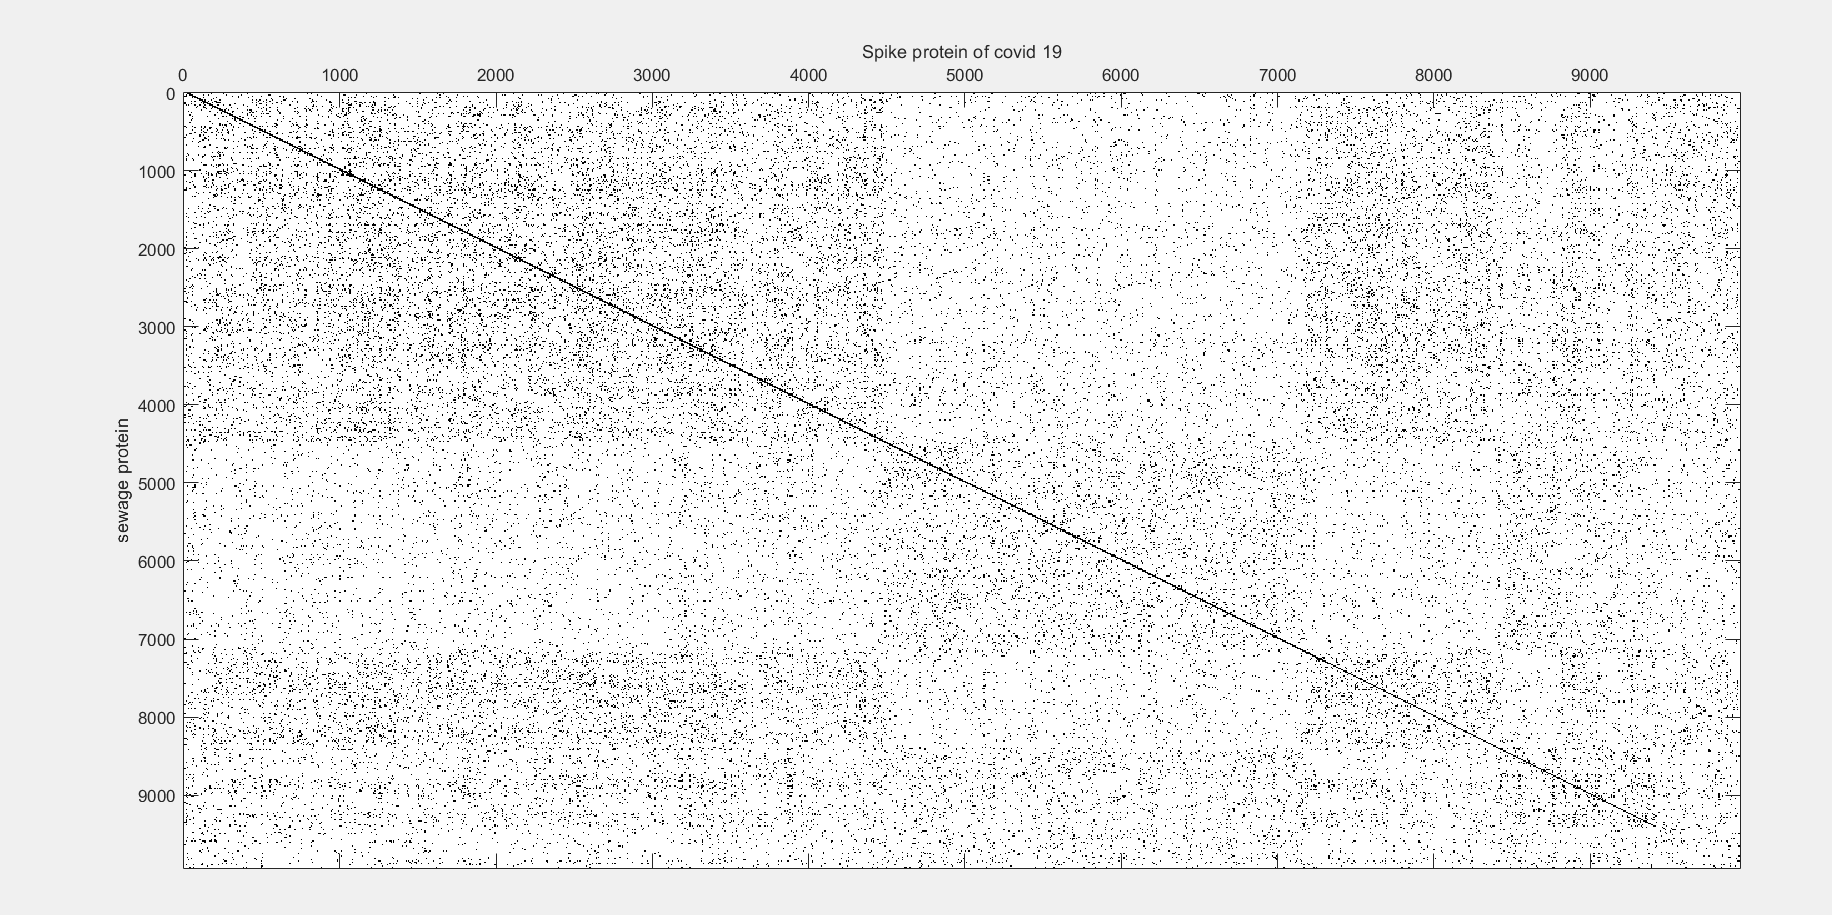

ylabel('sewage protein')
xlabel('Spike protein of covid 19')

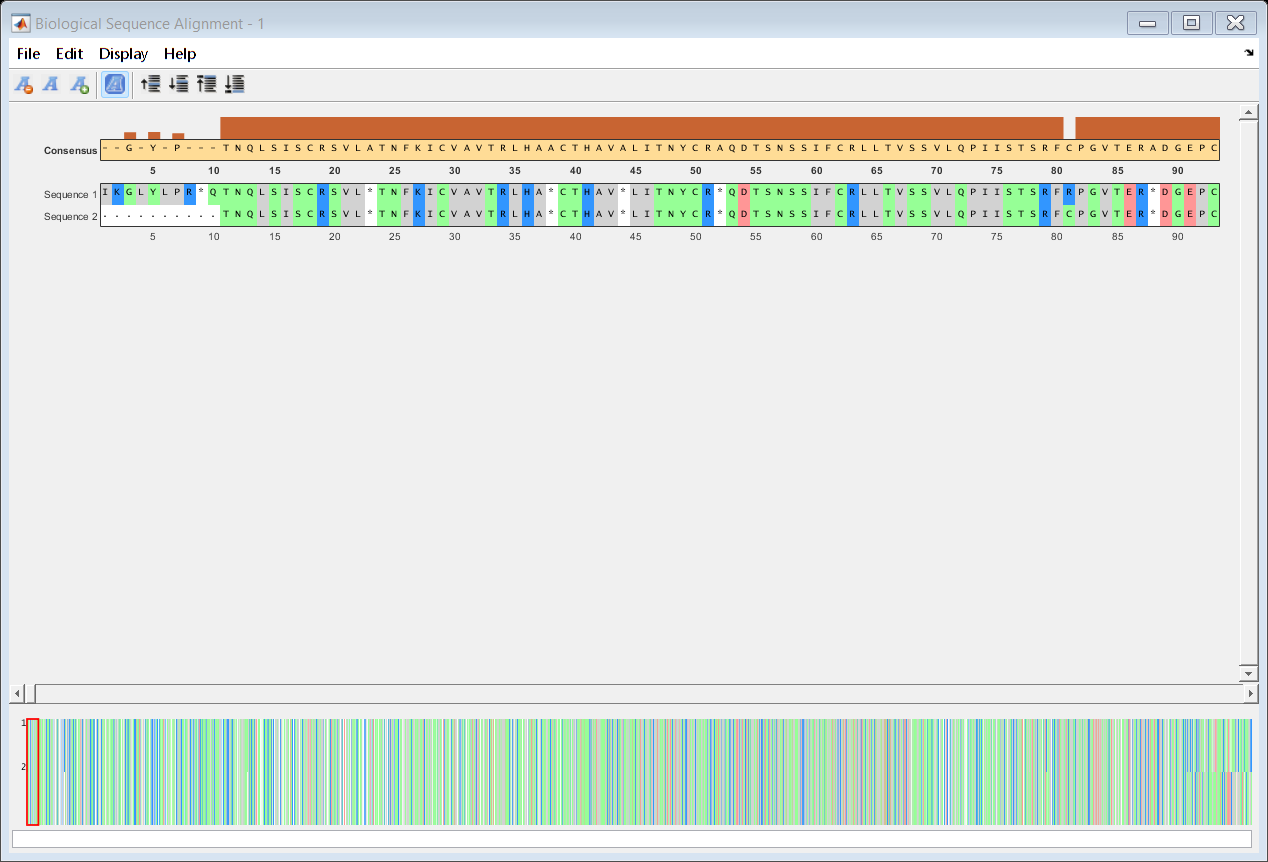

uif = gcf;%plot frame
figure;

%Needleman–Wunsch algorithm
[GlobalScore,GlobalAlignment]=nwalign(originprotein,sewageprotein);%score=how much matching; alignmnt=alignmnt of seq
seqalignviewer(GlobalAlignment);

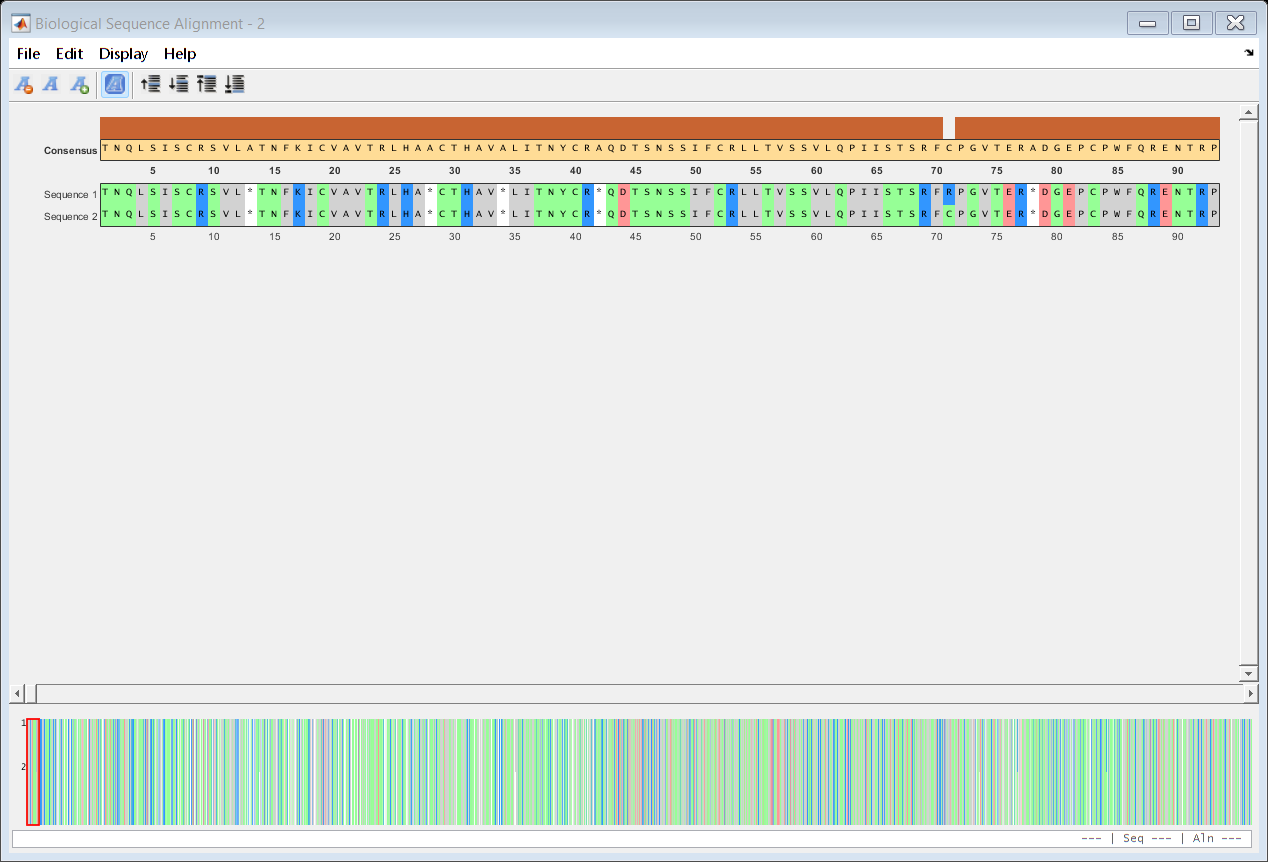


%Smith–Waterman algorithm
[LocalScore, LocalAlignment] = swalign(originprotein,sewageprotein);
seqalignviewer(LocalAlignment);

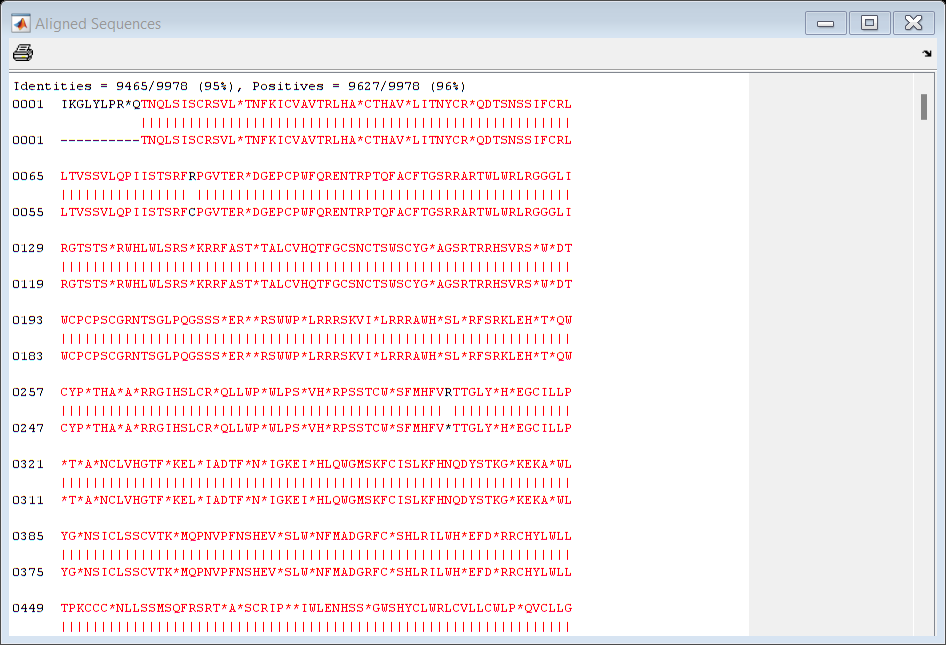


showalignment(GlobalAlignment)

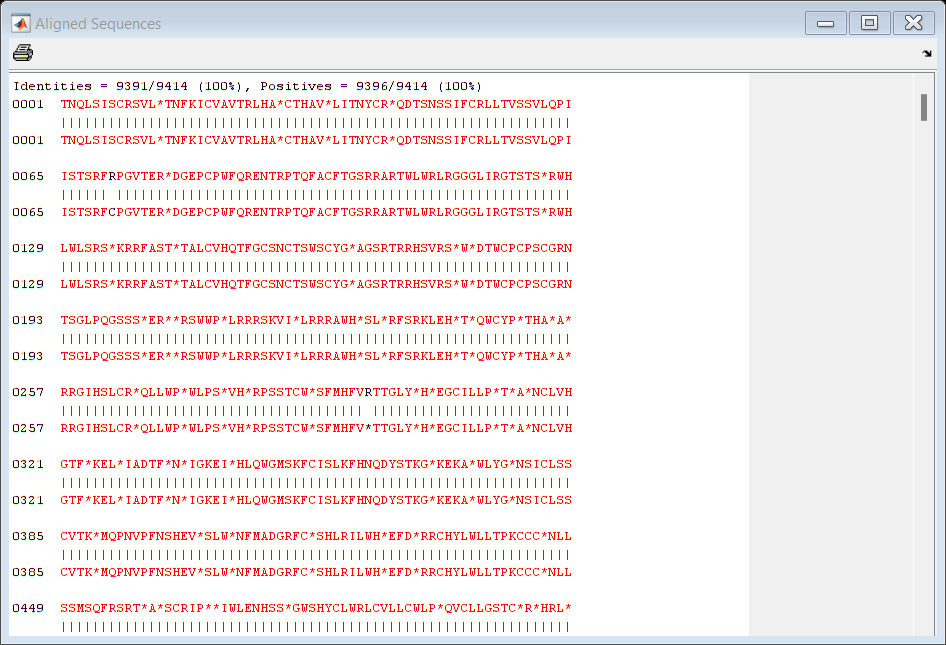

showalignment(LocalAlignment)